# Assessing the Occurrence of Tularemia in Cottontail Rabbits

## Introduction

This program has the following objectives:

- Load an external data file into an array.

- Compute descriptive statistics of the data. This will include several measures of central tendency, variability, asymmetry, and the importance of outliers.

- Produce several visualizations of the data including histograms and box and whisker plots.

- Fit a probability distribution to the data using parameter estimation.

- Qualitatively assess the fit of the distribution to the data by comparing the relative frequency histogram of the data set to a bar graph of the theoretical distribution.

- Quantitatively assess the fit of the distribution to the data by comparing the empirical shape parameters of the data to the theoretical shape parameters of the distribution.

- Quantitatively assess the fit of the distribution to the data by implementing Pearson's goodness of fit test.

- Load an additional data set into an array from an external file. This data represents new measurements taken after a condition of the physical system has been changed.

- Evaluate the significance of the change through two different hypothesis tests.

## Initialization Code

Clear all memory, close all figures, and clean out the command line history

clear all; close all; clc;

Read a control data set containing counts of rabbits diagnosed with tularemia out of 40 different samples of size 30, each taken from a habitat in a moderate climate.

data=csvread('DataExample.csv');

Read an experimental data set containing counts of rabbits diagnosed with tularemia out of 40 different samples of size 30, each taken from a habitat in a colder climate.

ExperimentalData=csvread('ExperimentalDataExample.csv');

## Descriptive Statistics

Compute some of the more useful descriptive statistics. 

The mean, median and mode are the three most commonly used measures of central tendency.

Mean=mean(data)

Mean = 9.5250

Median=median(data)

Median = 9.5000

Mode=mode(data)

Mode = 9

The three quartiles divide the sorted data set into four equal parts

Q=quantile(data,[0.25 0.50 0.75])

Q =     8.0000    9.5000   12.0000


InterQuartileRange=Q(3)-Q(1)

InterQuartileRange = 4

The maximum and minumum of the data set give us a measure of the extent covered by our data set. We can, in turn, use these to find the range of our data set.

Minimum=min(data)

Minimum = 5

Maximum=max(data)

Maximum = 14

Range=Maximum-Minimum

Range = 9

Variance and Standard Deviation are each measures of variability of the data around its mean

Variance=var(data,1)

Variance = 6.2994

StdDev=std(data,1)

StdDev = 2.5099

Skewness is a measure of asymmetry around the mean and Bowley's measure for skewness is a robust measure.

Skewness=skewness(data)

Skewness = -0.2145

Bowley=(Q(3)+Q(1)-2*Q(2))/InterQuartileRange

Bowley = 0.2500

Kurtosis is a measure of the variability of the extremities of the dataset about the mean.

Kurtosis=kurtosis(data)

Kurtosis = 2.0237

## Visualization

### Histogram

A histogram gives us an overall picture of how our data is distributed. 

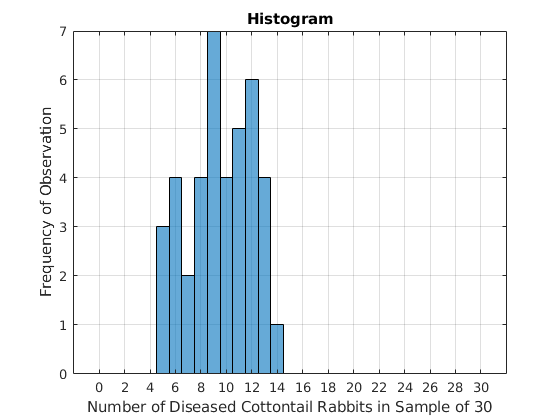

figure(1)
histogram(data,[-0.5:30.5])
title('Histogram');
xlabel('Number of Diseased Cottontail Rabbits in Sample of 30');
ylabel('Frequency of Observation');
xticks([0:2:30])
grid on

### Box and Whisker Plot

A box and whisker plot is a good way to visually summarize some of the descriptive statistics associated with our data set.  It also provides a visual measure of variability.

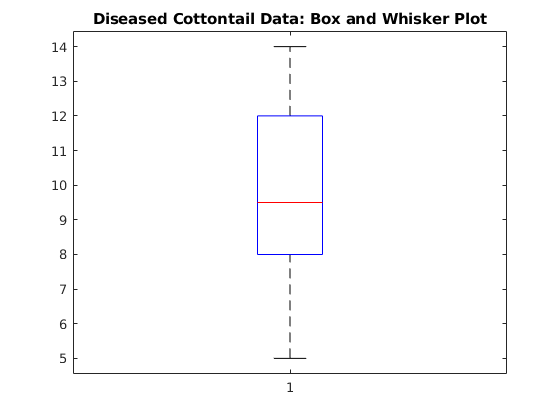

figure(2)
boxplot(data)
title('Diseased Cottontail Data: Box and Whisker Plot');

### Empirical Distribution

An empirical distribution is quite similar to a histogram, except that the bar heights represent relative frequencies of each outcome in the data set rather than absolute frequencies.

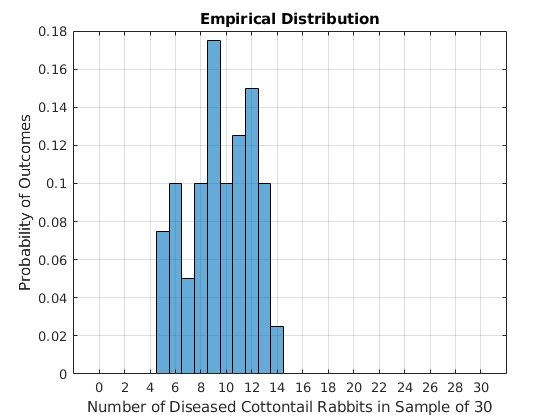

figure(3)
histogram(data,[-0.50:30.5],'Normalization','probability')
title('Empirical Distribution');
xlabel('Number of Diseased Cottontail Rabbits in Sample of 30');
ylabel('Probability of Outcomes')
xticks([0:2:30])
grid on

## Parameter Estimation

Mark and recapture with a marked group of K0=100 rabbits. Your approach should just use the built in mle function. Unfortunately, this won't work with the hypergeometric distribution, because it has discrete parameters. Instead, we just use mark and recapture based upon the method of moments estimates.

K0=100;
n=30;
xcaptures=[3,0,2,4,1,1,4,2]; 
N=n*K0/mean(xcaptures); 
N=round(N);
K=mean(data)*N/n;
K=round(K);

### Theoretical Distribution

Set the range of your random variable

x=0:30;

Compute values of the theoretical distribution over this range

y=hygepdf(x,N,K,n);

Plot the theoretical and empirical distributions together

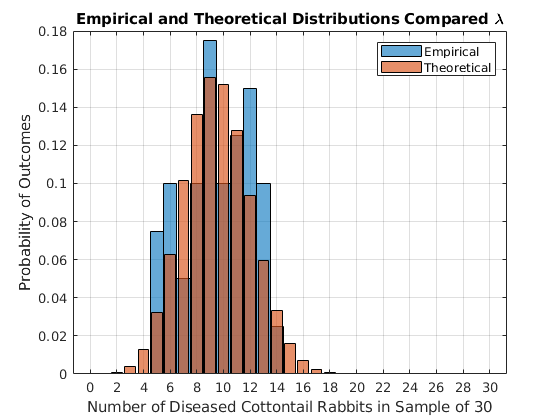

figure(4)
histogram(data,[-0.5:30.5],'Normalization','pdf')
title('Empirical and Theoretical Distributions Compared \lambda');
xlabel('Number of Diseased Cottontail Rabbits in Sample of 30');
ylabel('Probability of Outcomes')
xticks([0:2:30])
grid on
hold on
bar(x,y,'FaceAlpha',0.65)
legend('Empirical','Theoretical')
hold off

### Theoretical Shape Parameters for the Hypergeometric Histribution

MEAN=n*K/N; 
VAR=(n*K/N)*((N-K)/N)*((N-n)/(N-1));
SKEWNESS=((N-2*K)*sqrt(N-1)*(N-2*n))/(sqrt(n*K*(N-K)*(N-n))*(N-2));
KURTOSIS=((N-1)*(N^2)*(N*(N+1)-6*K*(N-K)-6*n*(N-n))+6*n*K*(N-K)*(N-n)*(5*N-6))/(n*K*(N-K)*(N-n)*(N-2)*(N-3))+3;
shapes=array2table([MEAN VAR SKEWNESS KURTOSIS; Mean Variance Skewness Kurtosis],'VariableNames',{'Mean','Variance','Skewness','Kurtosis'},'RowNames',{'Theoretical','Empirical'})

shapes = 2×4 table
                    Mean     Variance    Skewness    Kurtosis
                   ______    ________    ________    ________

    Theoretical    9.5184     6.3648      0.13889     2.9545 
    Empirical       9.525     6.2994     -0.21449     2.0237 


### Chi-squared goodness of fit test

Count the frequencies of each outcome $0\le x\le 30$

Create 5 bins of data chosen in order to ensure there are at least 5 observations per bin.  

edges=[-1,6,8,9,11,12,30] %endpoints for bins

edges =     -1     6     8     9    11    12    30


O=[7 6 7 9 6 5]; %observations in each bin
reps=length(data);
E=hygecdf(edges,N,K,n)*reps;
E=E(2:end)-E(1:end-1) %expected number of observations in each bin

E =     4.5257    9.5102    6.2233   11.1993    3.7461    4.7954


Prepare to compare the observed frequencies to the empirical frequeincies and then compute the $\chi^2$ test statistic.

frequencies=[O;E]

frequencies =     7.0000    6.0000    7.0000    9.0000    6.0000    5.0000
    4.5257    9.5102    6.2233   11.1993    3.7461    4.7954


chi2stat=sum(((O-E).^2)./E) %chi squared statistic

chi2stat = 4.5421

Graph the relevant chi-squared distribution

figure(5)
x=linspace(0,30,1000);

There are 6 bins for comparison, but we lose 2 degrees of freedom from estimating both N and K and one degree of freedom because there are a finite number of data points we've recorded.  Once we have assigned data points to any 5 of our 6 bins, there is no uncertainty in the number of data points that get assigned to the last bin.

df=3;

Visualize the chi squared distribution together with the test statistic.

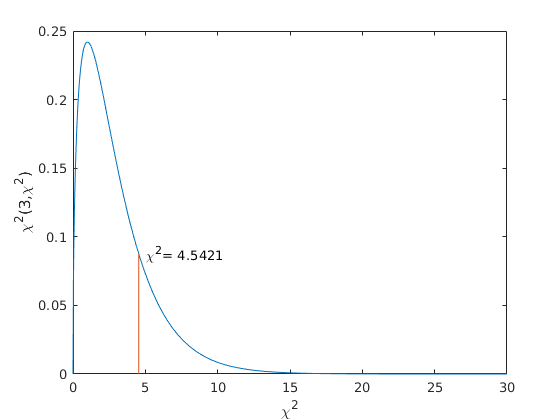

plot(x,chi2pdf(x,df),[chi2stat,chi2stat],[0,chi2pdf(chi2stat,df)])
xlabel('\chi^2')
ylabel('\chi^2(3,\chi^2)')
text(chi2stat+.5,chi2pdf(chi2stat,df),strjoin({'\chi^2=',num2str(chi2stat)}))

Assess the fit by computing a p value for the test statistic.

chi2P=chi2cdf(chi2stat,df,'upper')

chi2P = 0.2086

## Hypothesis Testing 

### Discrete Test

We are performing a test in the lower tail here because we are testing for a significant *decrease*.

PDec=hygecdf(ExperimentalData,N,K,n) 

PDec =     0.0051
    0.0502
    0.0051
    0.0502


We are performing a test in the lower tail here because we are testing for a significant *increase*.

PInc=1-hygecdf(ExperimentalData-1,N,K,n) 

PInc =     0.9989
    0.9818
    0.9989
    0.9818


T test for significant change in experimental sample mean
xb=mean(ExperimentalData);      %experimental sample mean
s=std(ExperimentalData);        %experimental sample std. dev.
ns=length(ExperimentalData);    %experimental sample size

t = -9.5582

t=(xb-MEAN)/(s/sqrt(ns))        %t statistic

nu = 3

nu=ns-1                         %degrees of freedom

We are performing a test in the lower tail because we are testing for a singificant *decrease*.

PDecT=tcdf(t,nu)                    

PDecT = 0.0012

We are performing a test in the upper tail because we are testing for a singificant *increase*.

PIncT=tcdf(t,nu,'upper')              

PIncT = 0.9988